%=====汉明窗设计低通滤波器====

fp = 1500; fs= 2500; Fs = 10000;

wpz = 2*fp/Fs;  wsz = 2*fs/Fs; 
wp = 2*pi*fp/Fs;  ws = 2*pi*fs/Fs

ws = 1.5708


Bt =  (ws - wp) % 滤波器过渡带宽度

Bt = 0.6283


wc = (wsz + wpz)/2  % 确定归一化中心频率

wc = 0.4000

N = 6.2*pi/Bt % 确定N

N = 31

M = N-1; % 计算阶数


% 确定阶数M
  

hnp1 = fir1(M , wc);

w = [0:0.01:pi]

w =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


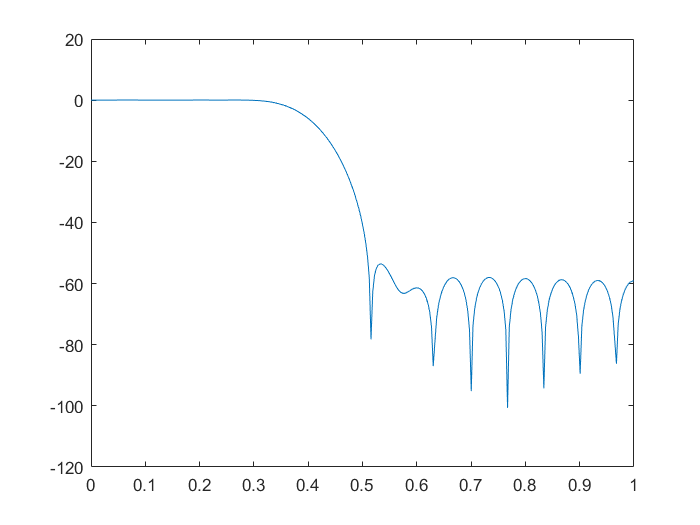

Hw = dtft(hnp1, w);
A = 20*log10(abs(Hw));
plot(w/pi, A);

汉宁窗设计高通滤波:

%=====汉明窗设计低通滤波器====

wpz= 0.5; wsz = 0.25;
wp = 0.5*pi; ws = 0.25*pi;


Bt =  (wp - ws) % 滤波器过渡带宽度

Bt = 0.7854

wc = (wsz + wpz)/2  % 确定归一化中心频率

wc = 0.3750


N0 = ceil(6.2*pi/Bt) % 确定N

N0 = 25

N = N0+mod(N0+1 , 2); %确保h(n) 长度N是奇数, 可以设计高通


M = N-1% 确定阶数M

M = 24

  

hnp1 = fir1(M , wc, 'high', hanning(N));

w = [0:0.01:pi]

w =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


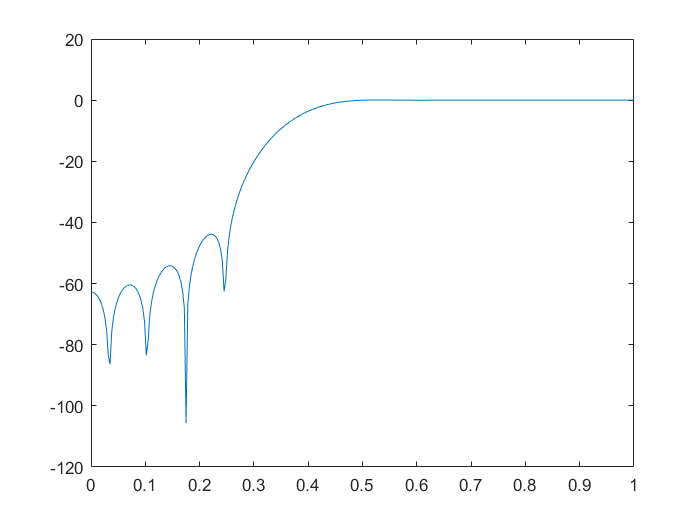

Hw = dtft(hnp1, w);
A = 20*log10(abs(Hw));
plot(w/pi, A);